## Pablo Vega Gallego, Adrian Cristian Crisan, Filip Gedung Dorm, VC, FIB. 

# Sessió 5

En aquest problema tractarem de trobar la solució d'un laberint partint de dos inicis: una bola blava i una bola verda; l'objectiu es anar a una bola vermella. 

Trobarem el camí mínim entre aquest parell de boles i pintarem aquest camí.

Primer llegirem la imatge del problema. 

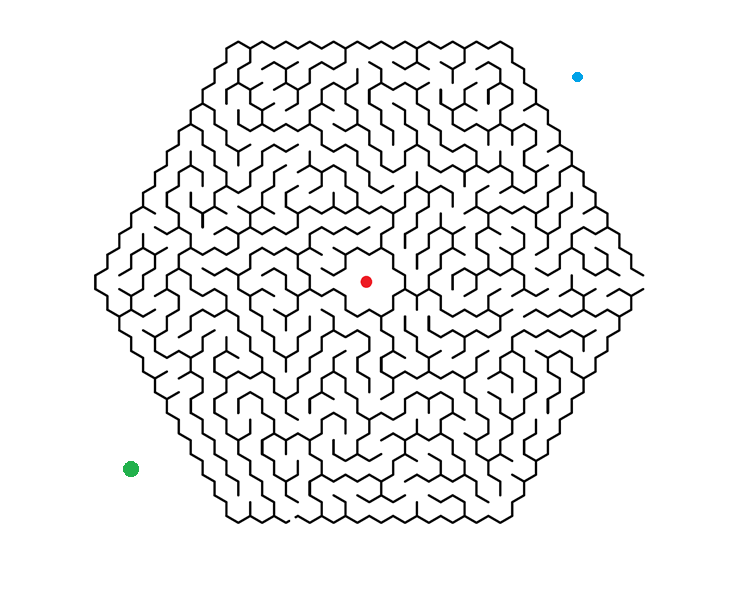

laberinto = imread('Laberint.png');
imshow(laberinto);

Convertirem la imatge a escala de grissos, per tal de poder trobar les bores més facilment.

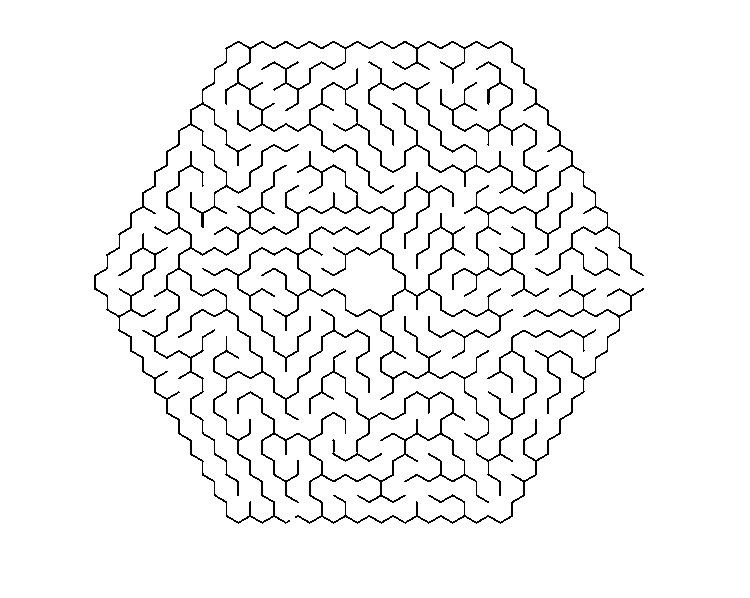

bordes = rgb2gray(laberinto);
bordes = bordes > 60;
imshow(bordes);

Ara realitzem una serie de comparacions per tal de poder trobar les boles a les imatges i binaritzar-les.

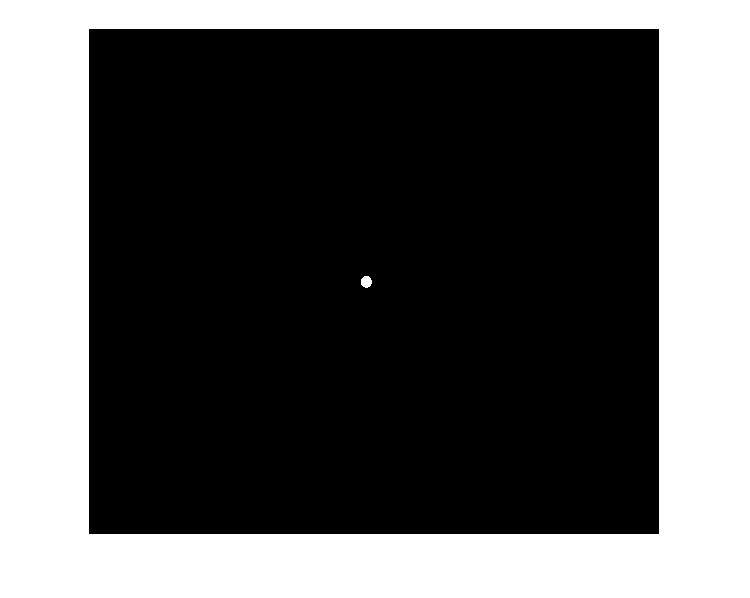

bola_roja = laberinto(:, :, 1) > 100 & laberinto(:, :, 2) < 100 & laberinto(:, :, 3) < 100;
imshow(bola_roja);

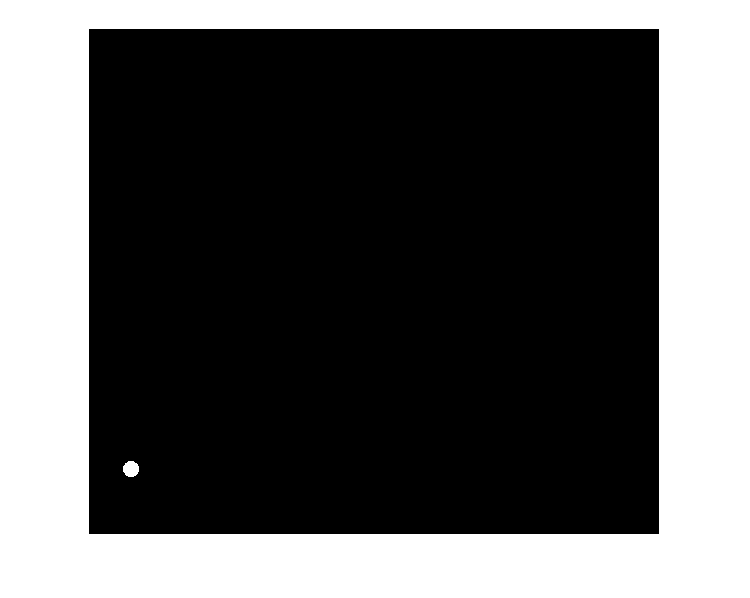

bola_verde = laberinto(:, :, 2) > 100 & laberinto(:, :, 1) < 100 & laberinto(:, :, 3) < 100;
imshow(bola_verde);

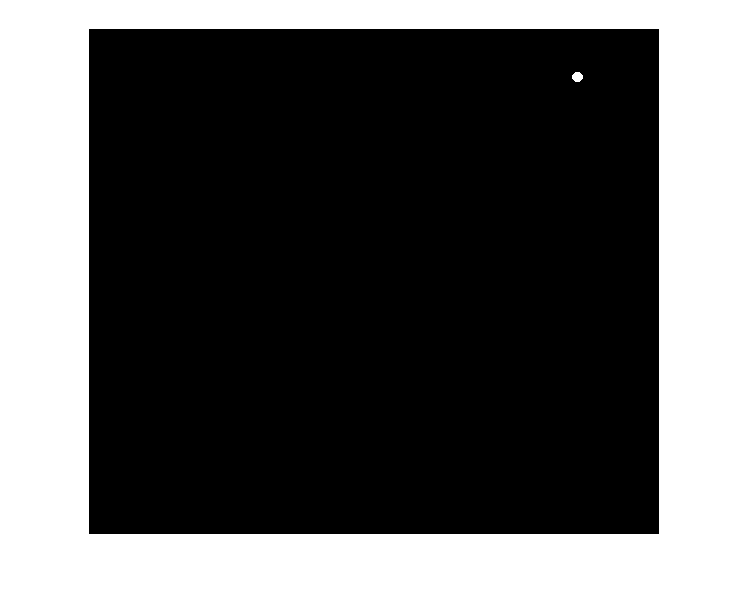

bola_azul = laberinto(:, :, 3) > 100 & laberinto(:, :, 2) < 200 & laberinto(:, :, 1) < 100;
imshow(bola_azul);

Un cop tenim el nostre espai ben dividit per: objectes i vores, ja podem començar a realitzar les operacions morfològiques per tal de trobar la solució òptima al laberint presentat.

Començarem creant un element estructural de veïnatge 8, cosa que farà que cada cop que dilatem la nostra imatge, augmenti en un píxel.

Després farem servir una funció anomenada 'espacio_visitado' que realitza les següents operacions: partim d'un inici, en aquest cas una de les boles, i possem com a objectiu una de les altres boles.

La funcionalitat consisteix en un bucle que va dilatant l'estat inicial constantment i talla aquesta dilatació amb les vores del laberint, cosa que ens impossibilita poder saltar-nos aquests obstacles.

Cada cop que realitza aquesta iteració, augmenta en un una variable, que resultarà ser la distància mínima que hi ha de l'inici al nostre objectiu.

SE = [1, 1, 1; 1, 1, 1; 1, 1 ,1];

[distancia_verde_rojo, espacio_visitado_verde_rojo] = espacio_visitado(bola_verde, bola_roja, bordes, SE);
[distancia_azul_rojo, espacio_visitado_azul_rojo] = espacio_visitado(bola_azul, bola_roja, bordes, SE);
display(distancia_verde_rojo); 

distancia_verde_rojo = 1013

display(distancia_azul_rojo);

distancia_azul_rojo = 1333

Aquesta imatge ens mostra l'espai que ha visitat la dilatació de l'estat inicial fins trobar l'estat final.

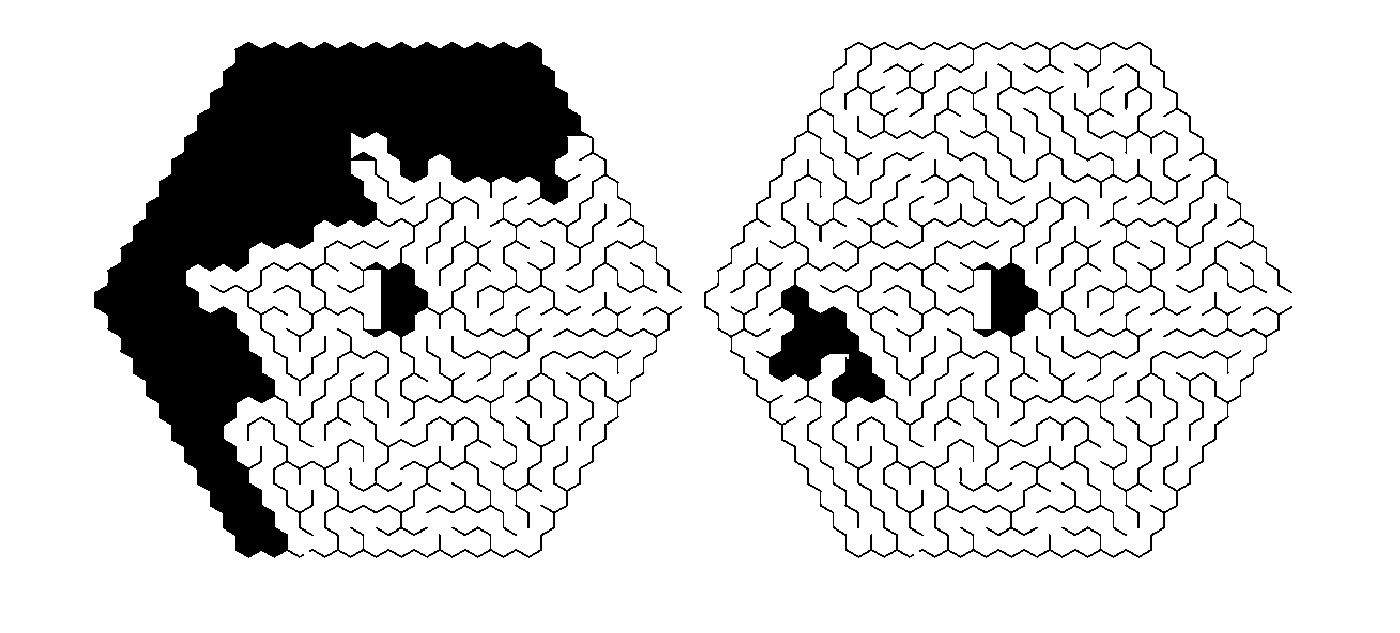

montage({espacio_visitado_verde_rojo, espacio_visitado_azul_rojo});

Ara per tal de trobar el camí mínim, aprofitarem per realitzar una matriu on anirem emmagatzemant la distància de cada píxel a l'estat inicial. Si fem aquesta feina de l'estat inicial cap al final i a l'inrevés, a l'hora de sumar aquestes dues matrius, els valors que siguin iguals a la distáncia mímina més 1, trobarem la zona per on passarà aquest camí mímim.

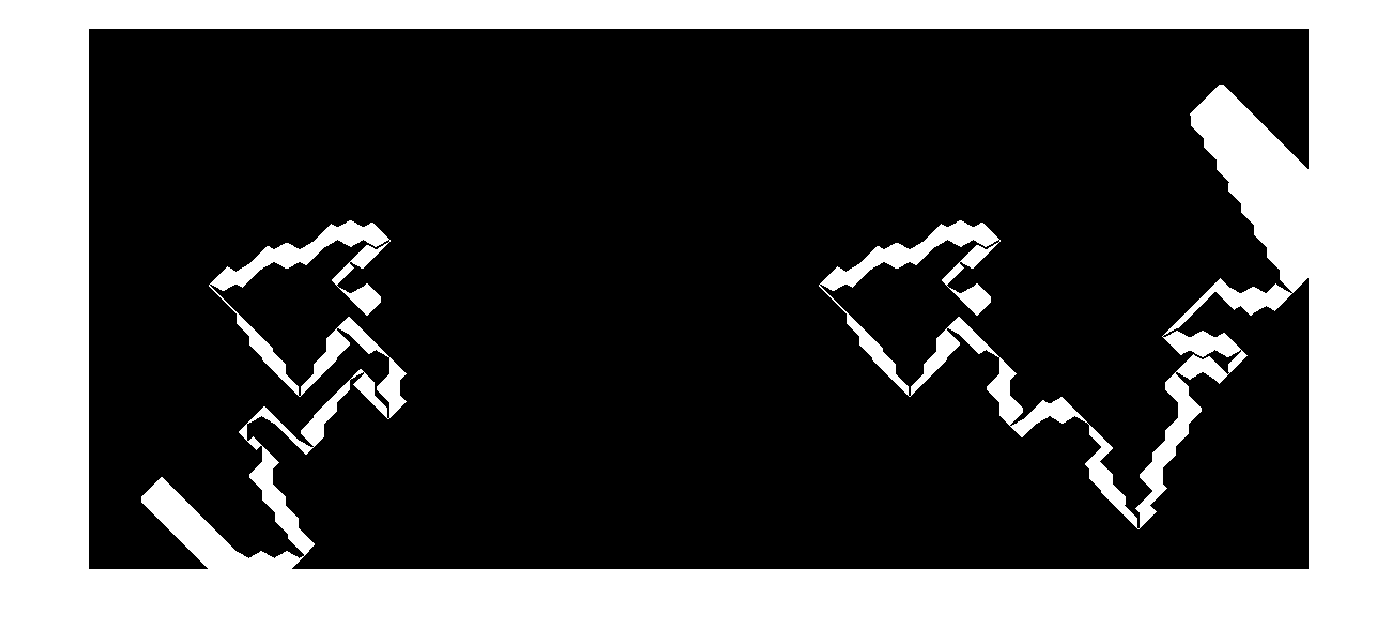

mapa_de_calor_verde_rojo = mapa_de_calor(bola_verde, bola_roja, bordes, SE);
mapa_de_calor_rojo_verde = mapa_de_calor(bola_roja, bola_verde, bordes, SE);

mapa_de_calor_azul_rojo = mapa_de_calor(bola_azul, bola_roja, bordes, SE);
mapa_de_calor_rojo_azul = mapa_de_calor(bola_roja, bola_azul, bordes, SE);

camino_verde_rojo = mapa_de_calor_verde_rojo + mapa_de_calor_rojo_verde;
camino_azul_rojo = mapa_de_calor_azul_rojo + mapa_de_calor_rojo_azul;

camino_verde_rojo = camino_verde_rojo == distancia_verde_rojo + 1;
camino_azul_rojo = camino_azul_rojo == distancia_azul_rojo + 1;

montage({camino_verde_rojo, camino_azul_rojo});

Després reduïm aquest camí que com podeu veure és bastant gors a una linia amb la funció de matlab, bwskel.

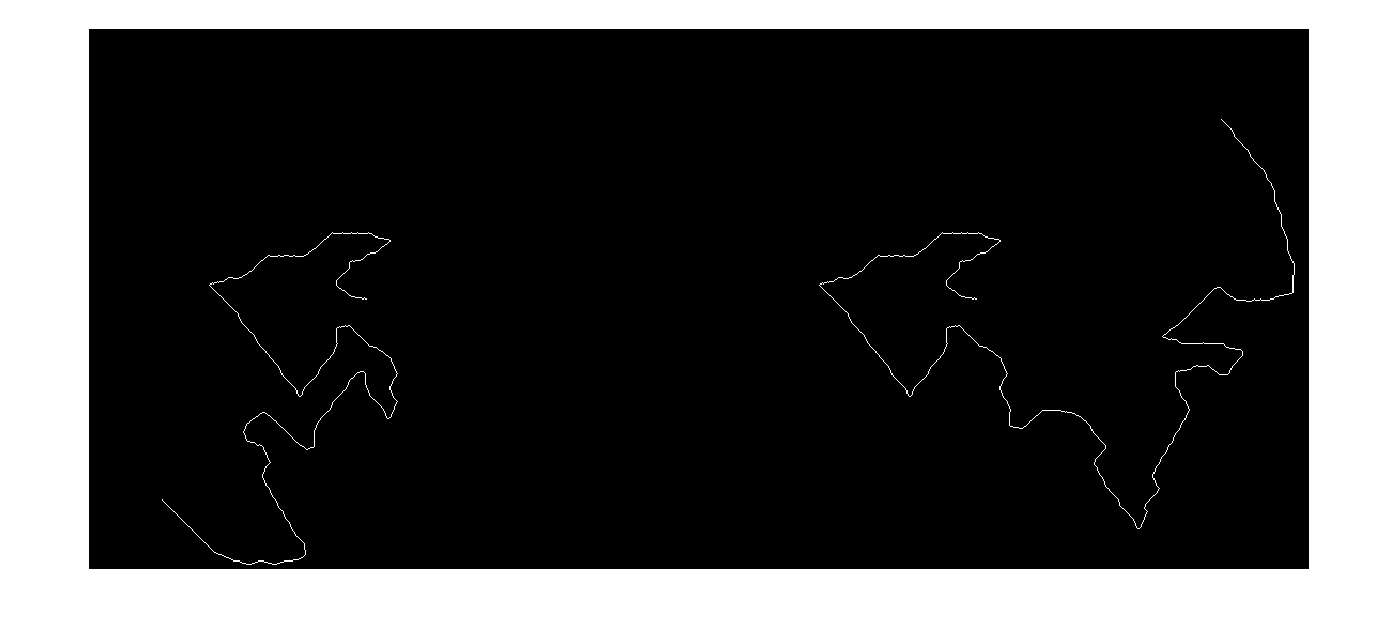

camino_verde_rojo = bwskel(camino_verde_rojo);
camino_azul_rojo = bwskel(camino_azul_rojo);

montage({camino_verde_rojo, camino_azul_rojo})

Dilatarem una mica la linia fent servir el mateix element estructural d'abans per tal de que la linia sigui més visible.

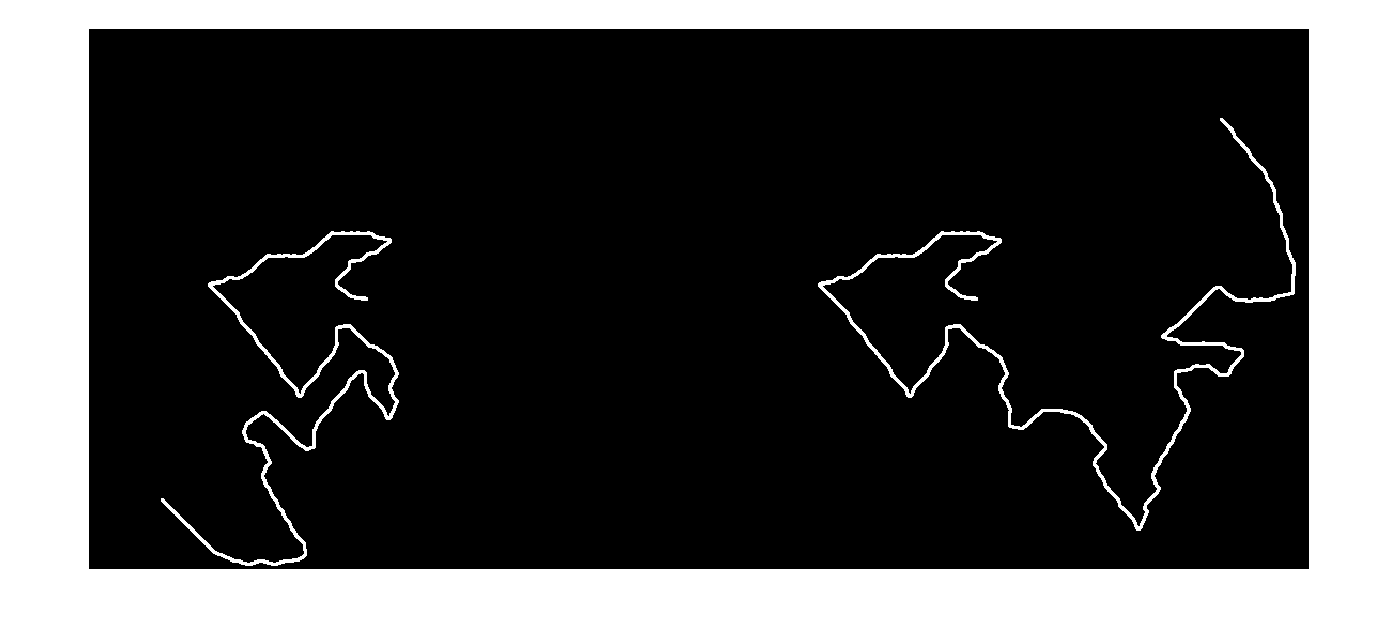

camino_verde_rojo = imdilate(camino_verde_rojo, SE);
camino_azul_rojo = imdilate(camino_azul_rojo, SE);

montage({camino_verde_rojo, camino_azul_rojo})

Finalment fem l'overlay de la imatge del camí amb l'orginal i pintem de groc aquest camí.

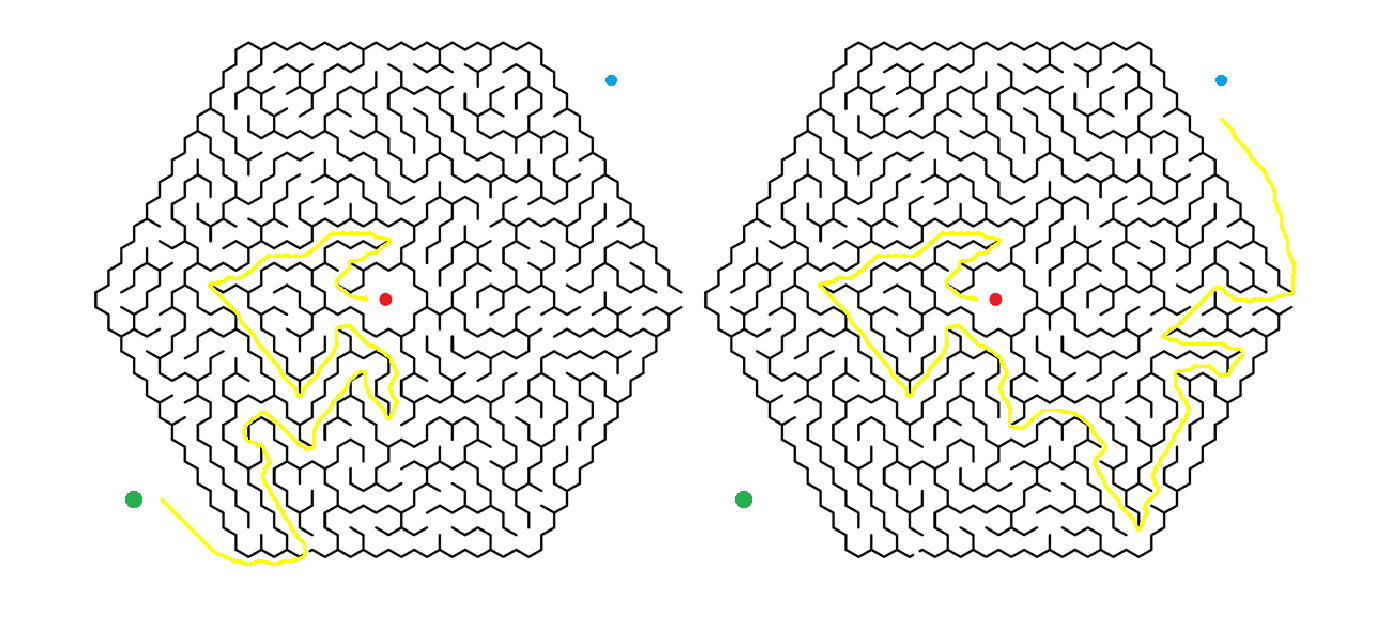

solucion_verde = imoverlay(laberinto, camino_verde_rojo, 'yellow');
solucion_azul = imoverlay(laberinto, camino_azul_rojo, 'yellow');

montage({solucion_verde, solucion_azul});

El camí mímim que hi ha és el de la bola verda a la vermella amb una distància de 1013 píxels.

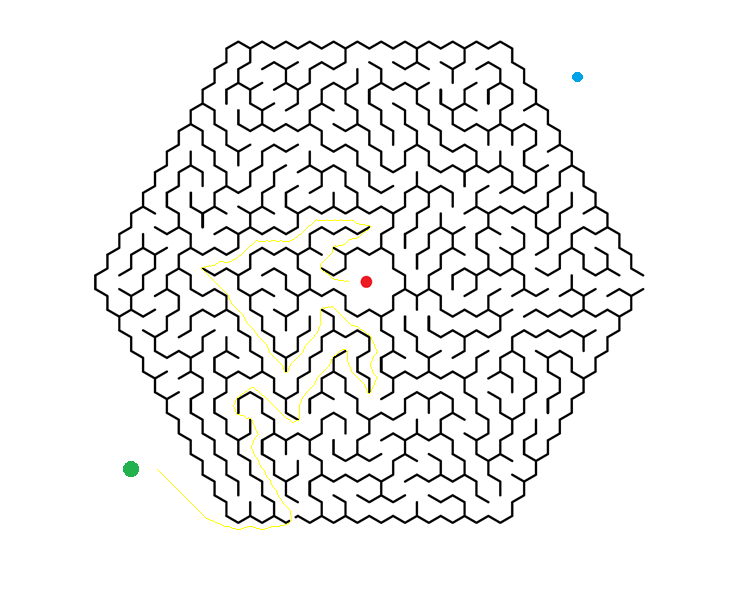

imshow(solucion_verde);

Funcions:

function [distancia, visitado] = espacio_visitado(estado_inicial, estado_final, bordes_lab, elemento_estructural)
    pixel = 1;
    
    while sum(sum(estado_final&estado_inicial)) == 0
        pixel = pixel + 1;
        estado_inicial = imdilate(estado_inicial, elemento_estructural);
        estado_inicial = estado_inicial&bordes_lab;
    end
    
    distancia = pixel;
    visitado = estado_inicial;
end

function mapa_de_grises = mapa_de_calor(estado_inicial, estado_final, bordes_lab, elemento_estructural)
    pixel = 1;
    distancias = im2double(estado_inicial);
    
    while sum(sum(estado_inicial&estado_final)) == 0
        pixel = pixel + 1;
        antes = estado_inicial;
        estado_inicial = imdilate(estado_inicial, elemento_estructural);
        estado_inicial = estado_inicial&bordes_lab;
        diferencia = estado_inicial - antes;
        distancias = distancias + diferencia .* pixel; 
    end
    
    mapa_de_grises = distancias;
end